# Analysis

#### Phase 1

Parameters

Adding matlab path to: D:\code\NN_molecular_communications\Section_IV_BioComputing\COMSOL_Three_Pipes
r_sensor=2 mm
Q_inlet_CNN=5 uL/min
height_pipe=36 um
c_Tartrazine_exp=0.08455 mol/L


c_max = 1

c_inlet=0.001 mol/L


mu = 9.9792e-04

D_coeff=4.9e-10 m^2/s



time_delta=0.01

time_delta = 0.0100

#### Phase 3: Load

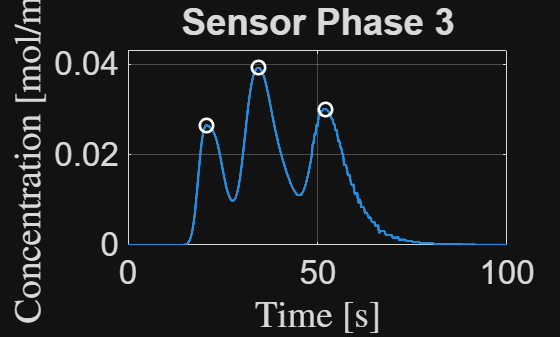

time_delta=0.01;

% Specify the CSV file
csvFileName = 'c_CNN_Phase_4.csv';
% Var 2- > alpha_outlet=0.65; time_delta=0.01

%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
Table_c_Pipe_CNN=readtable(csvFileName,opts);
t_COMSOL_Phase_4=(Table_c_Pipe_CNN.Var1);
c_COMSOL_CNN_Phase_4=(Table_c_Pipe_CNN.Var2);
h_COMSOL_CNN_Phase_4=gradient(c_COMSOL_CNN_Phase_4,t_COMSOL_Phase_4);

%finding the peaks
%First peak
[~,t_peak_A_COMSOL_Phase_4]=max(h_COMSOL_CNN_Phase_4(1:floor(end/4)));
t_peak_A_COMSOL_Phase_4=t_peak_A_COMSOL_Phase_4*time_delta;
%Second peak
x1=round(length(h_COMSOL_CNN_Phase_4)/3);
x2=round(2/3*length(h_COMSOL_CNN_Phase_4));
[~,t_peak_B_COMSOL_Phase_3]=max(h_COMSOL_CNN_Phase_4(x1:x2));
t_peak_B_COMSOL_Phase_3=(t_peak_B_COMSOL_Phase_3+x1)*time_delta;
%Third peak
x1=round(1/2*length(h_COMSOL_CNN_Phase_4));
x2=round(length(h_COMSOL_CNN_Phase_4));
[~,t_peak_C_COMSOL_Phase_3]=max(h_COMSOL_CNN_Phase_4(x1:x2));
t_peak_C_COMSOL_Phase_3=(t_peak_C_COMSOL_Phase_3+x1)*time_delta;


t=0:time_delta:time_simul;
figure;
% % plot(time,h_cir_1_Theo,'LineWidth',2); grid on; hold on;
plot(t_COMSOL_Phase_4,h_COMSOL_CNN_Phase_4,'LineWidth',2,'MarkerIndices',1:ceil(length(h_COMSOL_CNN_Phase_4)/15):length(h_COMSOL_CNN_Phase_4)); grid on; hold on;
plot(t_peak_A_COMSOL_Phase_4,h_COMSOL_CNN_Phase_4(round(t_peak_A_COMSOL_Phase_4/time_delta)),'ow','LineWidth',2,'MarkerSize',10); grid on; hold on;
plot(t_peak_B_COMSOL_Phase_3,h_COMSOL_CNN_Phase_4(round(t_peak_B_COMSOL_Phase_3/time_delta)),'ow','LineWidth',2,'MarkerSize',10); grid on; hold on;
plot(t_peak_C_COMSOL_Phase_3,h_COMSOL_CNN_Phase_4(round(t_peak_C_COMSOL_Phase_3/time_delta)),'ow','LineWidth',2,'MarkerSize',10); grid on; hold on;

xlabel('Time [s]','Interpreter','latex');
ylabel('Concentration [mol/m$^3$]','Interpreter','latex');
set(gca,'FontSize',fontsize);
title('Sensor Phase 3')
axis([0 t_COMSOL_Phase_4(end) 0 1.1*max(h_COMSOL_CNN_Phase_4)]);